# Homework 2

## Question 3: Control of dynamic systems

## a. Control of a second order dynamic system

Consider the dynamics system defined as


$$\bf{\ddot{x} + 5\dot{x} -4x = u
$$


Assume that you start from $\bf{x=0}$, $\bf{\dot{x}=0}$ and $\bf{u=0}$.

- Express the dynamics of the system in state space form and compute the eigen values of the system dynamics matrix. What can you say about the stability properties of the system.

- Compute the controllability matrix of the state-space equation you obtained.

- Using $\bf{u=0}$, numerically solve the the system dynamics equation to verify your predictions (use ode45).

- Use pole-placement technique to compute the gain matrix such that the eigen values of the modified system are at -2 and -3.

- Use this control law to achieve a desired set point given by $\bf{x=4}$. What can you say about the control thus generated? Is this control signal feasible?

- Use this control law to track a time-dependent signal given by $\bf{x(t)=sin(2t)}$. What can you say about the control thus generated? Is this control signal feasible?

## Solution a:


$$\bf{\dot{X} = \pmatrix{0&1\cr4&-5}X + \pmatrix{0\cr1}u$$


clc
close all
clear all

A = [0 1;4 -5];
B = [0;1];
[V,D] = eig(A)N

V =     0.8186   -0.1728
    0.5743    0.9850


D =     0.7016         0
         0   -5.7016


Since one the eigenvalues is greater than 0, this system is unstable and will diverge along the first eigenvector.

M_A = ctrb(A,B)%[B AB]

M_A =      0     1
     1    -5


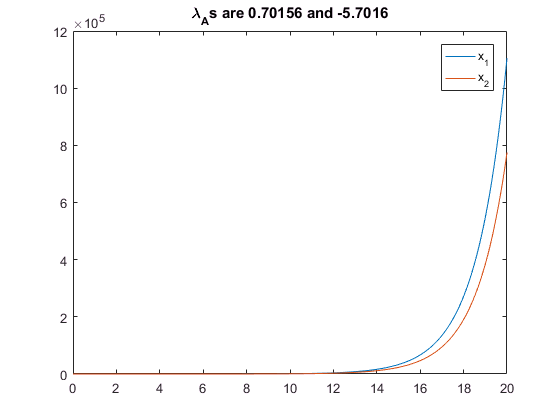

p = [-2;-3];
K = place(A,B,p);

sys_dyn = @(t,x)[A*x];
Tspan = 0:0.1:20;
x0 =[1;0];% We must start at x0 not equal to 0 to see the system diverge
[t,x] = ode45(sys_dyn, Tspan, x0);
plot(t,x)
legend('x_1','x_2')
title(['\lambda_As are ' num2str(D(1,1)) ' and ' num2str(D(2,2))])

Above we can see our prediction is confirmed. This system diverges as $\bf{t \rightarrow \infty$ for a non 0 starting state.

Using Pole Placement

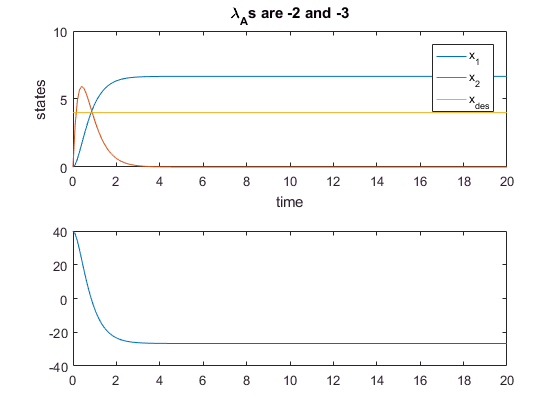

control = @(x)[-K*([x(1,:)-4;x(2,:)])];
sys_dyn = @(t,x)[A*x + B*control(x)];
x0 = [0;0];
[V,D] = eig(A-B*K);
[t,x] = ode45(sys_dyn, Tspan, x0);
figure;
subplot(2,1,1)
plot(t,x,t,4*ones(size(t)))
legend('x_1','x_2','x_{des}')
ylabel('states')
xlabel('time')
title(['\lambda_As are ' num2str(D(1,1)) ' and ' num2str(D(2,2))])

subplot(2,1,2)
plot(t,control(x'))

The control signal here definitely seems feasable, although a bit high. The error here is considerable though as we can see visually that it's over 50% of the desired setpoint


w = 2;

control = @(t,x)[-K*(x - [sin(w*t);w*cos(w*t)] )];
sys_dyn = @(t,x)[A*x + B*control(t,x)];
Tspan = 0:0.1:20;
x0 = [0;0];

[t,x] = ode45(sys_dyn,Tspan,x0);
figure;
subplot(2,1,1)
plot(t,x(:,1),t,sin(w*t))
legend('x_1','sin(t)')
title(['\lambda_A are ' num2str(D(1,1)) ' and ' num2str(D(2,2))])
subplot(2,1,2)
plot(t',control(t',x'))
err1 = norm(x(:,1)-sin(w*t))/norm(sin(w*t))

err1 = 1.2248

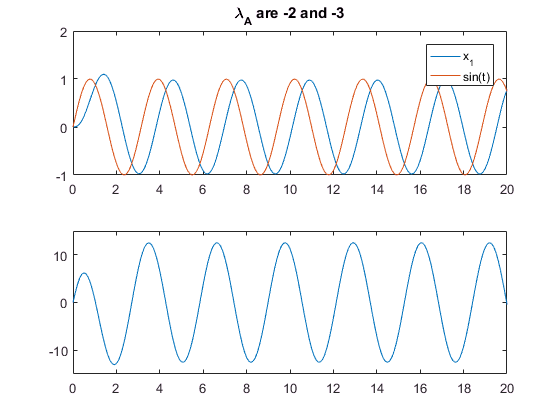

axis([0 20 -15 15])

Above we can see that our control signal is feasable however there is a clear phase difference between the actual and desired values. 

**b. Adding integrator error state **

- Modify your controller to add an additional state, the integral of the error between current and desired state.

- Use pole-placement technique to compute the gain matrix such that the eigen values of the modified system are at -2,-3 and -4.

- Use this control law to achieve a desired set point given by $\bf{x=4}$. What can you say about the control thus generated? Is this control signal feasible?

- Use this control law to track a time-dependent  signal given by $\bf{x(t)=sin(2t)}$. What can you say about the control thus generated? Is this control signal feasible?

## Solution b:

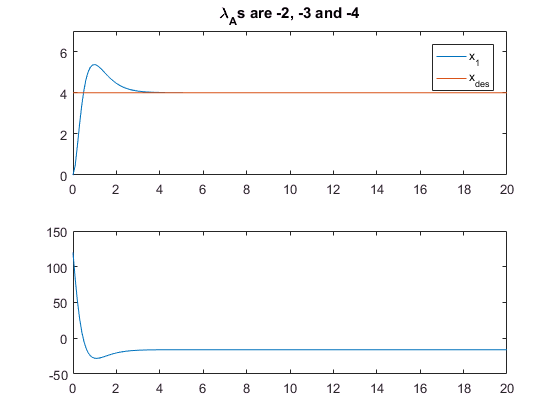

A = [0 1 0;0 0 1; 0 4 -5];
B = [0;0;1];

p = [-2;-3;-4];
K = place(A,B,p);
[v,d] = eig(A-B*K);

w = 2;

control = @(t,x)[-K*(x - [zeros(size(t));4*ones(size(t));zeros(size(t))] )];
sys_dyn = @(t,x)[A*x + B*control(t,x)-[4;0;0] ];
Tspan = 0:0.1:20;
x0 = [0;0;0]; 
[t,x] = ode45(sys_dyn,Tspan,x0);
figure;
subplot(2,1,1)
plot(t,x(:,2),t,4*ones(size(t)))
axis([0 20 0 7])
legend('x_1','x_{des}')
title(['\lambda_As are ' num2str(d(1,1)) ', ' num2str(d(2,2)) ' and ' num2str(d(3,3))])
subplot(2,1,2)
plot(t',control(t',x'))

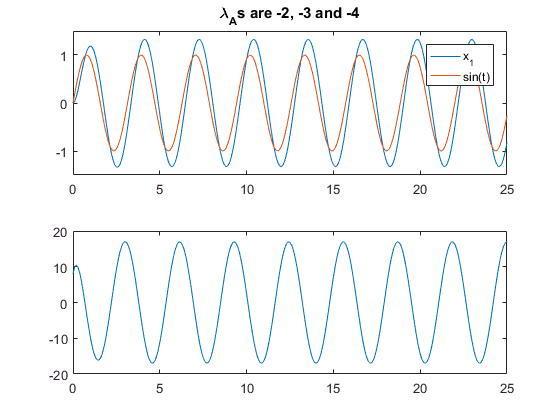



w = 2;

control = @(t,x)[-K*(x - [zeros(size(t));sin(w*t);w*cos(w*t)] )];
sys_dyn = @(t,x)[A*x + B*control(t,x)-[sin(w*t);0;0] ];
Tspan = 0:0.1:25;
x0 = [0;0;0];

[t,x] = ode45(sys_dyn,Tspan,x0);
figure;
subplot(2,1,1)
plot(t,x(:,2),t,sin(w*t))
axis([0 25 -1.5 1.5])
legend('x_1','sin(t)')
title(['\lambda_As are ' num2str(d(1,1)) ', ' num2str(d(2,2)) ' and ' num2str(d(3,3))])
subplot(2,1,2)
plot(t',control(t',x'))

err2 = norm(x(:,2)-sin(w*t))/norm(sin(w*t))

err2 = 0.5517

**c. Adding integrator error state and controller dynamic**[**¶**](https://mec560sbu.github.io/Assignments2016/MEC560_Assignment2_DUE_10032016.html#c.-Adding-integrator-error-state-and-controller-dynamic)

- Modify your controller to add an additional state, the integral of the error between current and desired state, and include first order actuator dynamics given by $\bf{\dot{u}=-5(u-u_c)}$.

- Use pole-placement technique to compute the gain matrix such that the eigen values of the modified system are at -2,-3,-4 and -5.

- Use this control law to achieve a desired set point given by $\bf{x=4}$. What can you say about the control thus generated? Is this control signal feasible?

- Use this control law to track a time-dependent signal given by $\bf{x(t)=sin(2t)}$. What can you say about the control thus generated? Is this control signal feasible?

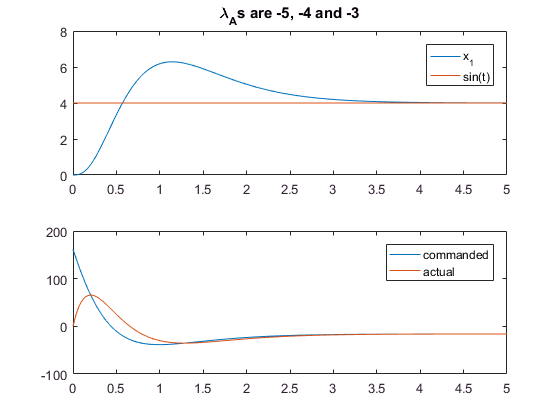

A = [0 1 0 0; 0 0 1 0;0 4 -5 1; 0 0 0 -5];
B = [0 ;0 ;0;5];

p = [-2;-3;-4;-5];
K = place(A,B,p);
[V,D] = eig(A-B*K);



control = @(t,x)[-K*(x - [zeros(size(t));4*ones(size(t));zeros(size(t));3*4*ones(size(t))] )];
sys_dyn = @(t,x)[A*x + B*control(t,x)-[4;0;0;0] ];
Tspan = 0:0.02:5;
x0 = [0;0;0;0];

[t,x] = ode45(sys_dyn,Tspan,x0);
figure;
subplot(2,1,1)
plot(t,x(:,2),t,4*ones(size(t)))
legend('x_1','sin(t)')
title(['\lambda_As are ' num2str(D(1,1)) ', ' num2str(D(2,2)) ' and ' num2str(D(3,3))])
subplot(2,1,2)
plot(t',control(t',x'),t',x(:,4)')
legend('commanded','actual')

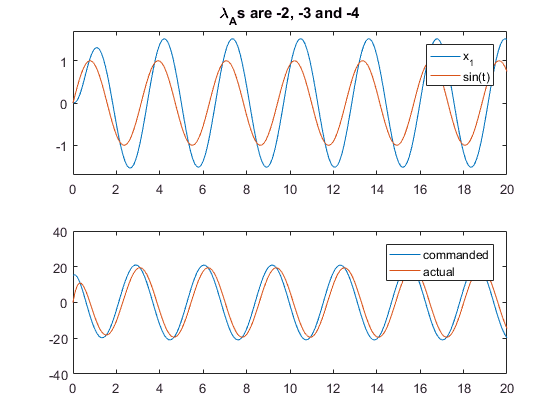

w = 2;

control = @(t,x)[-K*(x - [zeros(size(t));sin(w*t);w*cos(w*t);-w^2*sin(w*t)+2*w*cos(w*t)+3*sin(w*t)] )];

sys_dyn = @(t,x)[A*x + B*control(t,x)-[sin(w*t);0;0;0] ];
Tspan = 0:0.1:20;
x0 = [0;0;0;0];

[t,x] = ode45(sys_dyn,Tspan,x0);
figure;
subplot(2,1,1)
plot(t,x(:,2),t,sin(w*t))
axis([0 20 -1.7 1.7])
legend('x_1','sin(t)')
title(['\lambda_As are ' num2str(d(1,1)) ', ' num2str(d(2,2)) ' and ' num2str(d(3,3))])
subplot(2,1,2)
plot(t',control(t',x'),t',x(:,4)')
legend('commanded','actual')

err3 = norm(x(:,2)-sin(w*t))/norm(sin(w*t))

err3 = 0.8277

cerr = norm(x(:,4)' - control(t',x'))/norm(control(t',x'))

cerr = 0.3843

Compare the controllers from parts a,b and c, and make a recommendation of which controller you will choose and why?